# Audio file read

[data, fs] = audioread('c:\windows\media\chimes.wav')

data =          0   -0.0000
   -0.0000         0
         0   -0.0000
         0         0
         0         0
   -0.0000         0
         0         0
   -0.0000         0
         0         0
         0   -0.0000


fs = 44100


%sound(data, fs)


## Process Data

monosignal = sum(data')' / 2

monosignal =    -0.0000
   -0.0000
   -0.0000
         0
         0
   -0.0000
         0
   -0.0000
         0
   -0.0000


sound(monosignal, fs)


## Backwards

len = max(size(data))

len = 54080

%sound(data(len:-1:1, :), fs*.8)

max(abs(data))

ans =     0.0489    0.0612


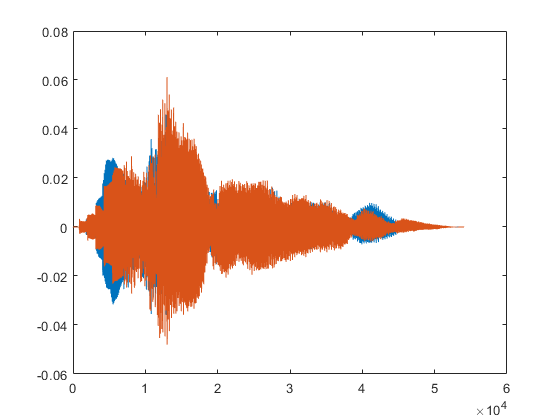


hardrock = data ; 
hardrock(hardrock >  0.02) =  0.02 ;
hardrock(hardrock < -0.02) = -0.02 ;

sound(hardrock, fs)

plot(data)

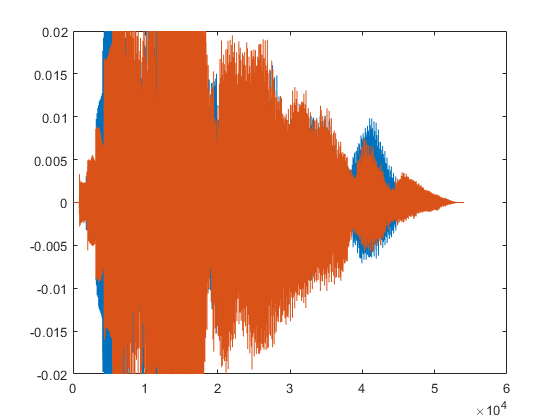

plot(hardrock)

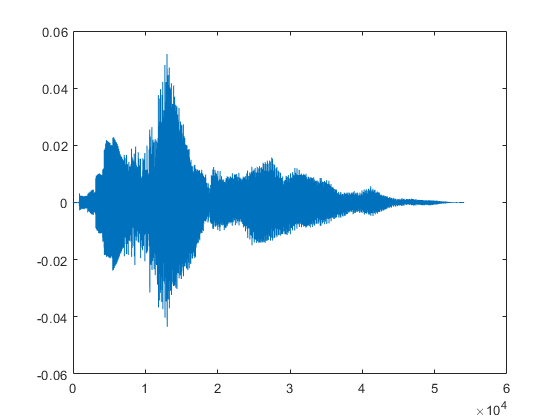

plot(monosignal)